L_1 = 13;
L_2 = 8;
L_3 = 3;
L_4 = 8;
L_5 = 2;
L_6 = 3;
theta_1 = 0*pi/180;
theta_2 = 0*pi/180;
theta_3 = 45*pi/180;
theta_4 = 0*pi/180;
theta_5 = 0*pi/180;
theta_6 = 0*pi/180;
L(1) = Link([theta_1 L_1 0 -pi/2]);
L(2) = Link([theta_2 -3 L_2 0]);
L(3) = Link([theta_3+pi/2  -L_3 0 pi/2]);
L(4) = Link([theta_4 L_4 0 -pi/2]);
L(5) = Link([theta_5-pi/2  0 0 pi/2]);
L(6) = Link([theta_6 L_5 + L_6 0 0]);
Puma_260 = SerialLink(L)

 
Puma_260 = 
 
noname:: 6 axis, RRRRRR, stdDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         13|          0|    -1.5708|          0|
|  2|         q2|         -3|          8|          0|          0|
|  3|         q3|         -3|          0|     1.5708|          0|
|  4|         q4|          8|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          5|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


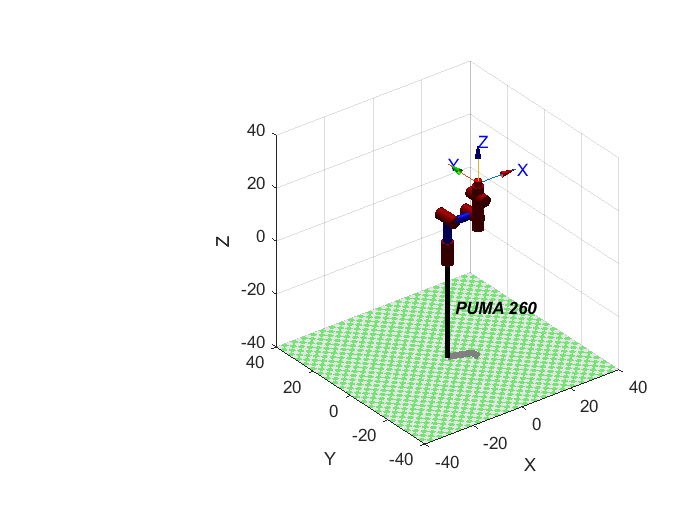

Puma_260.name = 'PUMA 260';
Puma_260.teach

A1 = DH_A(0,  -pi/2,   L_1, theta_1);
A2 = DH_A(L_2,     0,  0, theta_2);
A3 = DH_A(0, pi/2,  -L_3, theta_3 + pi/2);
A4 = DH_A(0,  -pi/2,   L_4, theta_4);
A5 = DH_A(0, pi/2,   0, theta_5 - pi/2);
A6 = DH_A(0,     0,   L_5 + L_6, theta_6);

T06 = A1*A2*A3*A4*A5*A6

T06 =     0.7071   -0.0000    0.7071   17.1924
    0.0000    1.0000    0.0000   -3.0000
   -0.7071    0.0000    0.7071   10.8787
         0         0         0    1.0000


 q = Puma_260.ikine(T06)

q =     0.2273    0.9469    0.5192    0.2472   -0.7089   -0.3514


function A=DH_A(a,alpha,d,theta)

A=[cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha) a*cos(theta);...
  sin(theta) cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);...
  0 sin(alpha) cos(alpha) d;...
  0 0 0 1];
end

